Iniciando la grabación...


Grabación completada.


Audio guardado como "GrabacionAudio_2023-10-30_17-18-32.wav"


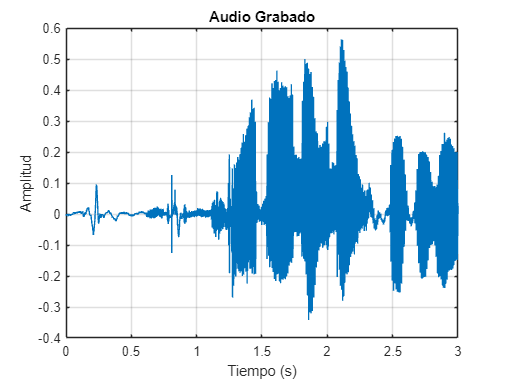

clc, clear vars, close all

while true
    % Menú para seleccionar los parámetros de grabación
    dlg_title = 'Opciones de Grabación de Audio';
    prompt = {'Frec. Muestreo (Hz):', 'Bits/muestra:', 'Tipo de Grabación (mono o estéreo):', 'Tiempo de Grabación (s)'};
    num_lines = 1;
    defaultans = {'44100', '16', 'mono', '3'};
    
    answer = inputdlg(prompt, dlg_title, num_lines, defaultans);
    
    Fs1 = str2num(answer{1}); % Frecuencia de muestreo
    nBit = str2num(answer{2}); % Número de bits por muestra
    tipoGrabacion = answer{3}; % Tipo de grabación (mono o estéreo)
    tRec1 = str2num(answer{4}); % Tiempo de grabación en s.

    if strcmp(tipoGrabacion, 'mono')
        nChan = 1; % Grabación mono
    elseif strcmp(tipoGrabacion, 'estéreo')
        nChan = 2; % Grabación estéreo
    else
        disp('Opción no válida para el tipo de grabación. Usando mono por defecto.');
        nChan = 1; % Valor predeterminado: grabación mono
    end

    aud1 = audiorecorder(Fs1, nBit, nChan); % Crear un objeto audiorecorder

    % Crear un objeto uiprogressdlg con título e icono
    fig = uifigure;

    tRec = tRec1; % Tiempo de grabación en s.

    d = uiprogressdlg(fig, 'Title', ['Grabando audio (' num2str(tRec) ' seconds)'], 'Icon', "RecordAudio.jpg");

    disp('Iniciando la grabación...');

    d.Message = sprintf('Hable ahora!! %.1f segundos', 0.1);

    recordblocking(aud1, tRec); % Grabar audio

    % Actualizar la barra de avance y el mensaje cada 0.1 segundos
    delta = 0.1;
    for i = 0.2:delta:tRec - delta
        d.Value = i / tRec;
        d.Message = sprintf('Tiempo transcurrido: %.1f segundos', i);
        pause(0.1);
    end
    % Cerrar el diálogo de progreso
    close(d);
    close(fig);

    % Mostrar mensaje de grabación completada
    disp('Grabación completada.');

    % Reproducir el audio grabado
    play(aud1);

    % Esperar a que termine la reproducción
    pause(tRec + 1); % Esperar más tiempo del que dura la grabación

    % Obtener los datos de la señal
    y = getaudiodata(aud1);

    % Guardar los datos en un archivo WAV
    filename = ['GrabacionAudio_' datestr(now, 'yyyy-mm-dd_HH-MM-SS') '.wav'];
    audiowrite(filename, y, Fs1);
    disp(['Audio guardado como "' filename '"']);

    % Visualizar la señal
    t = (0:length(y) - 1) / Fs1; % Crear un vector de tiempo
    figure;
    plot(t, y);
    title('Audio Grabado');
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    grid on;

    % Preguntar al usuario si desea realizar otra grabación
    another_recording = input('¿Desea realizar otra grabación? (y/n): ', 's');
    if lower(another_recording) ~= 'y'
        break; % Salir del bucle si el usuario no desea otra grabación
    end
end